rgb_monk = zeros(10,3);
rgb_monk(1,:) = rgb(246, 237, 228);
rgb_monk(2,:) = rgb(243, 231, 219);
rgb_monk(3,:) = rgb(247, 234, 208);
rgb_monk(4,:) = rgb(234, 218, 186);
rgb_monk(5,:) = rgb(215, 189, 150);
rgb_monk(6,:) = rgb(160, 126, 86);
rgb_monk(7,:) = rgb(130, 92, 67);
rgb_monk(8,:) = rgb(96, 65, 52);
rgb_monk(9,:) = rgb(58, 49, 42);
rgb_monk(10,:) = rgb(41, 36, 32);

lab_monk = rgb2lab(rgb_monk/255);
dist = 0.1;

%
% Fitzpatrick
%
rgb_fitzpatrick = zeros(6,3);
rgb_fitzpatrick(1,:) = [241 220 219];
rgb_fitzpatrick(2,:) = [229 185 200];
rgb_fitzpatrick(3,:) = [220 175 133];
rgb_fitzpatrick(4,:) = [162 127 97];
rgb_fitzpatrick(5,:) = [81 58 40];
rgb_fitzpatrick(6,:) = [10 9 7];
lab_fitzpatrick = rgb2lab(rgb_fitzpatrick/255);
marker_fitzpatrick = {"I", "II", "III", "IV", "V", "VI"}

marker_fitzpatrick = 1×6 cell array
    {["I"]}    {["II"]}    {["III"]}    {["IV"]}    {["V"]}    {["VI"]}


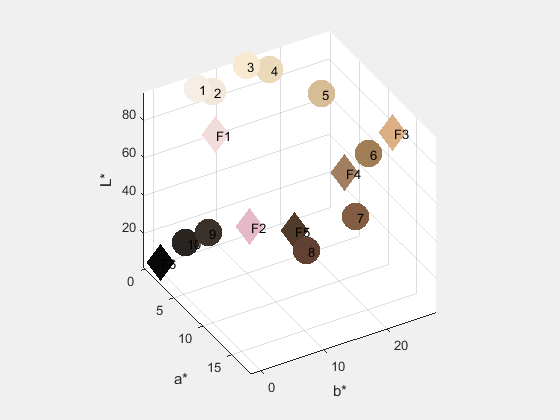


clf
hg = gcf;
set(gcf,'Visible','on')
hold on
for i=1:10
    plot3(lab_monk(i,2),lab_monk(i,3),lab_monk(i,1),'o','MarkerSize',20,'MarkerFaceColor',rgb_monk(i,:)/255,'MarkerEdgeColor',rgb_monk(i,:)/255)
    text(lab_monk(i,2)+dist,lab_monk(i,3)+dist,lab_monk(i,1),sprintf('%d',i))
end

for i=1:6
    plot3(lab_fitzpatrick(i,2),lab_fitzpatrick(i,3),lab_fitzpatrick(i,1),'d','MarkerSize',20,'MarkerFaceColor',rgb_fitzpatrick(i,:)/255,'MarkerEdgeColor',rgb_fitzpatrick(i,:)/255)
    text(lab_fitzpatrick(i,2)+dist,lab_fitzpatrick(i,3)+dist,lab_fitzpatrick(i,1),marker_fitzpatrick{i})
end

xlabel('a*')
ylabel('b*')
zlabel('L*')
grid on
view(60,35)

create_animation ('skin_color_in_CIELAB.gif')

function val = rgb (r,g,b)
    val = [r g b];
end

